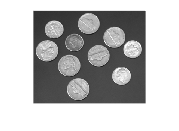

img = imread('coins.png');% Read image
imshow(img);


% Check if image is already grayscale
if size(img, 3) == 3                      % RGB image
    gray_img = rgb2gray(img);  
else                                       % Already grayscale
    gray_img = img;  
end

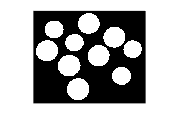


bw = imbinarize(gray_img);                % Binarize the image
bw = imfill(bw, 'holes');  
imshow(bw);

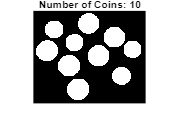

               % Fill holes inside the coins

% Apply morphological operations to remove noise
se = strel('disk', 15);                   % Structuring element (adjust size)
bw_clean = imopen(bw, se);                % Remove small noise
bw_clean = bwareaopen(bw_clean, 500);     % Remove very small regions

% Count connected components
stats = regionprops(bw_clean, 'Area');    % Detect regions
num_coins = numel(stats);                 % Count the regions

imshow(bw_clean);                         % Display cleaned image
title(['Number of Coins: ', num2str(num_coins)]);

disp(['Number of coins: ', num2str(num_coins)]);

Number of coins: 10
